# Import/Export Data

Often, we want to use MATLAB to manipulate data generated with other software. Similarly, we might want to create data in MATLAB that can be used in other programs. This requires us to understand importing and exporting data with MATLAB.

## A Typical Example – Manipulating Grades

Manipulating grades is a classic example used to discuss importing/exporting data. It is convenient to create gradebooks using electronic spreadsheet software (e.g., Excel), but the data manipulation is often cleaner using a scientific programming language (e.g., MATLAB). Consider the Excel data shown in the screenshot below. We want to import this data to MATLAB and manipulate it accordingly.

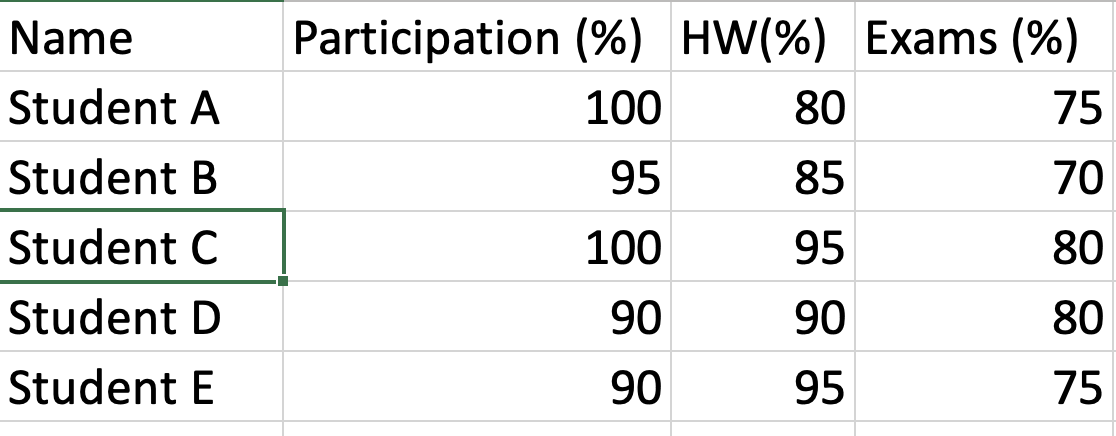

There are a few ways we can import this data. Let's first focus on just the numerical values, which is the most important stuff, anyway. When all the data we want to import is numerical, we can directly import it to a matrix. We do this using the [`readmatrix`](https://www.mathworks.com/help/matlab/ref/readmatrix.html) command in MATLAB. The simplest way to use this command is

This stores the data from the desired file to a matrix (`A`). 

 A = readmatrix('Grades.xlsx') % store the data in Grades.xlsx to the variable A

A =    NaN   100    80    75
   NaN    95    85    70
   NaN   100    95    80
   NaN    90    90    80
   NaN    90    95    75


Notice that the first row of the data (the column headers) was not imported and that the first column was imported but stored as 'NaN' (not a number). This is a consequence of some default settings of the `readmatrix` command:

- The first row is ignored if all the entries are `NaN`

- All other entries are imported as their numerical values or `NaN`

We don't want the `NaN` column, since that is just a placeholder for the students' names. There are many ways we can remove this column. One way is using the [`rmmissing`](https://www.mathworks.com/help/matlab/ref/rmmissing.html?s_tid=doc_ta) command, which can remove rows or columns of matrices that have missing data.

A = rmmissing(A,2); % remove columns of A that have missing data (e.g., NaN)
% Note: 2 refers to looking into columns
disp(A)

   100    80    75
    95    85    70
   100    95    80
    90    90    80
    90    95    75


Now that the grade data is stored to a matrix, we can manipulate it just like any other matrix.

Create a new column in matrix `A` that represents the overall grade for each student. Use the bin weight represented by the vector `w`, defined below.

w = [10 30 60]; % overall grade bin weight, in %
format short
A(:,4) = sum(A.*w/100,2) % create 4th column of A

A =   100.0000   80.0000   75.0000   79.0000
   95.0000   85.0000   70.0000   77.0000
  100.0000   95.0000   80.0000   86.5000
   90.0000   90.0000   80.0000   84.0000
   90.0000   95.0000   75.0000   82.5000


Now that we have calculated each student's overall course grade, we would like to export the grades back to Excel. We can do this using [`writematrix`](https://www.mathworks.com/help/matlab/ref/writematrix.html?s_tid=doc_ta). The general syntax is

writematrix(A,'Grades_Final.xlsx') % write matrix A to a file called Grades_Final.xlsx

Note that `A` does not have the first row (the column headers) or the first column (the student names) contained in the original Grades file. There are a few ways we could fix this. The most straightforward way is to probably have imported the original Grades data as a table instead of a matrix.

## MATLAB Table Arrays

[Table arrays](https://www.mathworks.com/help/matlab/ref/table.html?searchHighlight=table&s_tid=srchtitle_table_1) allow us to store strings (i.e., words) and doubles (i.e., numbers) to the same variable. We can read in data to a table using [`readtable`](https://www.mathworks.com/help/matlab/ref/readtable.html).

T = readtable('Grades.xlsx') % create table T from Grades.xlsx

T = 5×4 table
        Name         Participation___    HW___    Exams___
    _____________    ________________    _____    ________
    {'Student A'}          100            80         75   
    {'Student B'}           95            85         70   
    {'Student C'}          100            95         80   
    {'Student D'}           90            90         80   
    {'Student E'}           90            95         75   

The `readtable` function reads in the table headers as variable names. The warning is due to the fact that variable names in MATLAB can't have spaces or special characters (e.g., % and parentheses), so these characters are converted to underscores in the table header row. There are many ways to access data in a table.

Access the values in a column using the syntax

T.Participation___

ans =    100
    95
   100
    90
    90


Create smaller tables by calling select elements using the syntax

Note that the first row of the table is the row below the table headers. For example, to create a new table excluding student A, we write

T2 = T(2:end,:) % 2:end means from row 2 until the rows end

T2 = 4×4 table
        Name         Participation___    HW___    Exams___
    _____________    ________________    _____    ________
    {'Student B'}           95            85         70   
    {'Student C'}          100            95         80   
    {'Student D'}           90            90         80   
    {'Student E'}           90            95         75   

Create a matrix of select entries using the syntax

For this to work, all the entries must be of the same data type (e.g., double or string). To create a matrix of just the numerical percentages of the grades for each student, we write

G = T{:,2:end} % Matrix created

G =    100    80    75
    95    85    70
   100    95    80
    90    90    80
    90    95    75


To append a column to a table, we use the syntax

Create new column of T with the variable name `Final_Grade` that represents each student's final grade. The bin weights are copied again below for convenience.

w = [10 30 60]; % overall grade bin weight, in %
T.Final_Grade = sum(G.*w/100,2)

T = 5×5 table
        Name         Participation___    HW___    Exams___    Final_Grade
    _____________    ________________    _____    ________    ___________
    {'Student A'}          100            80         75            79    
    {'Student B'}           95            85         70            77    
    {'Student C'}          100            95         80          86.5    
    {'Student D'}           90            90         80            84    
    {'Student E'}           90            95         75          82.5    

Now we can write this table to a file using `writetable`. Let's write the table to a text file.

writetable(T,'Final_Grades.txt')